**Week 9:**

The first goal is to implement the noise free one dimensional model, as described in the lecture. 

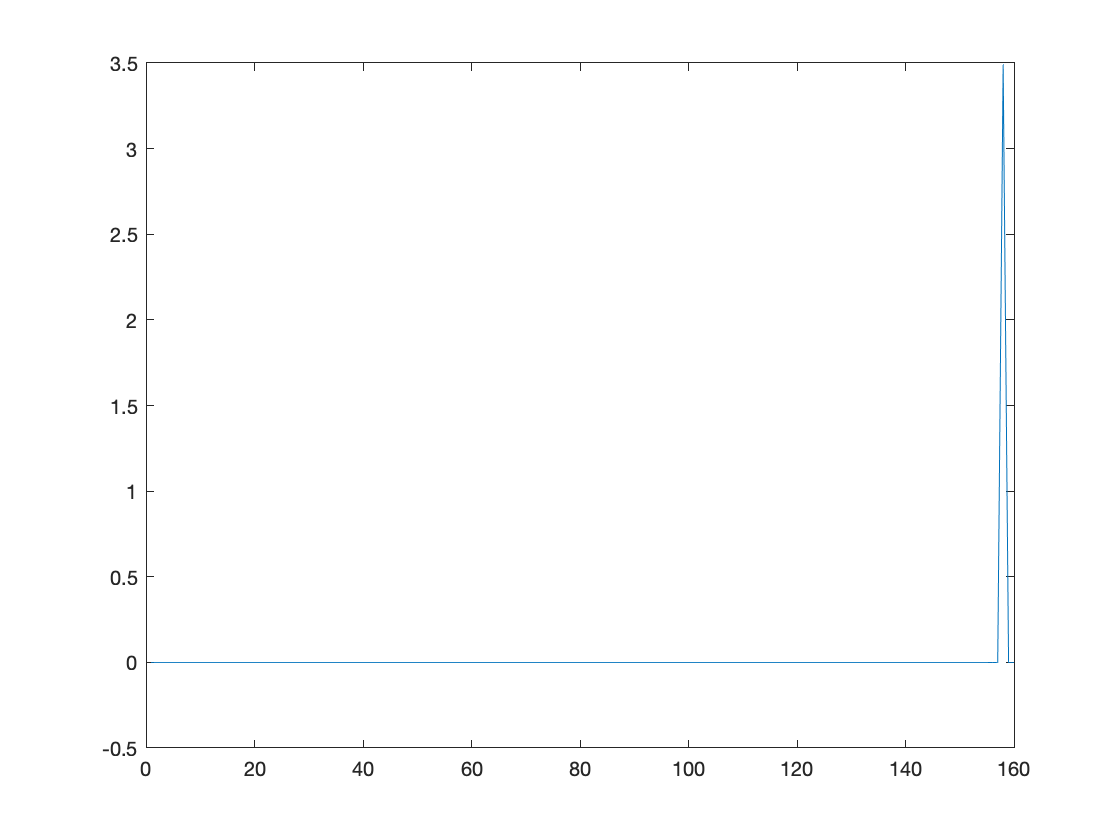

%noise free 1D system
g=50 ;%the size of the saccade
G= g*pi/180;%the extend of the saccade in radians
r=[G;0;0];
x_0=[0;0;0];
p_r=linspace(10,200,190+1);%the p values in ms 
p=160;%the value indicated on page 7
b=(224+13);%*10^(-3);%setting b as the experimentally shown value (see page 4 of lecture notes)
a1=4;%*10^(-3);%same for a
m=224*13;%*10^(-3); %the value of m from page 4
k=1; %the value of k from page 4
C=eye(3);
%Gamma=b*eye(p);
v=[5*10^(7) 1*10^(4) 0.8];
T=zeros(3,3);
T(1,1)=v(1);
T(2,2)=v(2);
T(3,3)=v(3);
L=eye(p); %set L as an identity matrix as suggested on page 5
bm= [0;0;1/a1]; %as stated on page 4
Gamma=zeros(3*p,p);
A=[[0 1 0];[-k/m -b/m 1/m];[0 0 -k/a1]]; %as stated on page 4 and 5
F=zeros(3,3*p);
loc=zeros(3,p);
for i =1:p
    F(:,i:i+2)=A^(p-i);
    Gamma(i:i+2,i)=bm;
end
%u=[];
%for i=1:p
%    u(p)=inv(1+bm'*(A.^(p-i))'*C'*T*C*(A.^(p-i))*bm)*bm'*(A.^(p-i))'*C'*T*(r-C*(A.^(p))*x_0);
    %disp(inv(1+bm'*(A.^(p-i))'*C'*T*C*(A.^(p-i))*bm))
    %disp(bm'*(A.^(p-i))'*C'*T*(r-C*(A.^(p))*x_0))
%end
%plot(u);
u=u_det(L,Gamma,F,C,T,A^(p),r,x_0);
for i =i:p
    loc(:,i)=x_k(i,A,x_0,F,Gamma,u);
end

J=[];
for o = 1:length(p_r)
    J(o)=J_scal(L,Gamma,F,C,T,A.^(p),r,x_0,u,1.8*10^5,5,p_r(o));
end
plot(u)

**The required functions:**

As in matlab the functions need to be at the bottom of the file I will define them here:

function [u]=u_det(L,Gamma,F,C,T,A_p,r,x_0)
ft=inv(L+Gamma'*F'*C'*T*C*F*Gamma);
st=Gamma'*F'*C'*T;
lt=r-C*(A_p)*x_0;
u=ft*st*lt;
end
function [x]=x_k(p,A,x_0,F,Gamma,u)
x=(A.^p)*x_0+F*Gamma*u;
end
function [y]=y_k(C,x)
y=C*x;
end
function [J]=J_scal(L,Gamma,F,C,T,A_p,r,x_0,u,alpha,beta,p) 
ft=x_0'*A_p'+u'*Gamma'*F';
st=C'*T*C;
fts=A_p*x_0+F*Gamma*u;
ftt=-2*(x_0'*A_p'+u'*Gamma'*F')*C'*T*r;
fttr=r'*T*r;
tt=u'*L*u;
frt=alpha*(1-1/(1+beta*p));
J=ft*st*fts+ftt+fttr+tt+frt;
end